# **Speaker Recognition using Mel-Frequency Cepstrum (MFC),  and Eigendecomposition**

# Ian Walsh and Sparsh Gupta

**Dataset source:** MNIST Audio

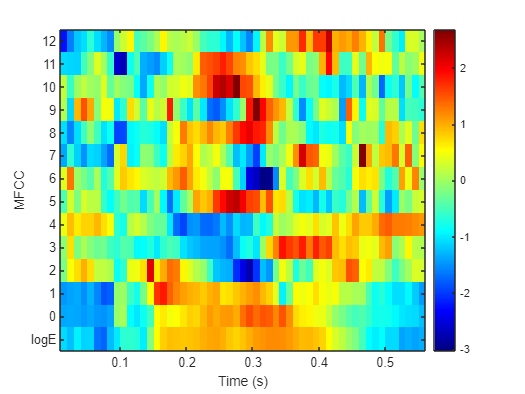

%QEA Fall 2022
%Ian Walsh and Sparsh Gupta Final Project
clc; clear; close all;

% Gesture Classes (Also Filenames)
accentTypes = ["01", "02", "03", "04"];

numAccents = length(accentTypes);
filesPerAccent = 50;

accentLabels = zeros(numAccents,filesPerAccent);
fftFrequencies = 200;

audioArrayNames = strings(numAccents, filesPerAccent);
audioArrayFFT = zeros(fftFrequencies, 14, filesPerAccent, numAccents);

% Create labels for each accent (80 samples x 6 accents)
for labelMaker = 1:numAccents
    accentLabels(labelMaker, 1:filesPerAccent) = labelMaker;
end

minSamples = 90000;

for i = 1:numAccents
    % Get metadata list for each directory
    fileMetadata = dir("Training Data/" + accentTypes(i));
    for nameParser = 1:min(length(fileMetadata) - 3, filesPerAccent)

       % Parse out names of audio files
       audioArrayNames(i, nameParser) = fileMetadata(nameParser + 3).name;
       
       % Read the audio files (mono voltage level x numSamples)
       [f,fs] = audioread("Training Data/" + accentTypes(i) + "/" + audioArrayNames(i, nameParser));
        
       % FFT on audio files
       tempFFT = mfcc(f, fs);

      % tempFFT = abs(tempFFT(1:fftFrequencies));

       %Convert from complex FFT output ttempFFTo real numbers.
       %We only care about the first 20k samples as they correspond to a DC-20kHz frequency spectrum
       audioArrayFFT(1:size(tempFFT, 1), :, nameParser, i) = tempFFT;
       %if(size(tempFFT, 1) > minSamples)
       if(size(tempFFT, 1) < minSamples)
           minSamples = size(tempFFT, 1);
       end
    end
end

mfcc(f, fs)


numTrain = filesPerAccent / 2;
numTest = filesPerAccent / 2;
% data initialization
trainData = audioArrayFFT(1:minSamples, :, 1:numTrain, :);
testData  = audioArrayFFT(1:minSamples, :, numTrain:numTrain+numTest, :);

train_data2 = zeros(minSamples * 14, numTrain, numAccents);
test_data2 = zeros(minSamples * 14, numTest, numAccents);

% data labels initialization
accentsLabels_train = zeros(numTrain, numAccents);
accentsLabels_test = zeros(numTest, numAccents);
%accentsLabels_test = zeros(numTest,numAccents);

for i = 1:numTrain
    for j = 1:numAccents
        temptemp = trainData(:, :, i, j);
        train_data2(:,i, j) = reshape(temptemp, [], 1);
    end
end

for i = 1:numTest
    for j = 1:numAccents
        temptemp = testData(:, :, i, j);
        test_data2(:,i, j) = reshape(temptemp, [], 1);
    end
end

train_data = reshape(train_data2, [], numTrain * numAccents);
test_data = reshape(test_data2, [], numTest * numAccents);

%train_data(:,:,:) 
% data manipulation
for i=1:numAccents

    for k=1:numTrain
        accentsLabels_train(k,i) = accentLabels(i,k);
    end
    for k=1:numTest
        accentsLabels_test(k,i) = accentLabels(i,k);
    end

end

% number of files in each dataset(equal split between train data & test data)
n = numAccents * numTrain;


% reshape data labels
accentsLabels_train = reshape(accentsLabels_train, [], 1);


% eigendecomposition

c_train = train_data' * train_data;

[V_train, D_train] = eig(c_train);

U = train_data * V_train;

% training set weights
weights_train = zeros(n, n);

for i=1:n
    weights_train(:,i) = project(train_data(:,i), U, n);
end

% prediction on test set
test_pred = zeros(n, 1);

for i=1:n
    test_pred(i) = predict_accent(test_data(:,i), U, n, weights_train, accentsLabels_train);
end

accentsLabels_test = reshape(accentsLabels_test, [], 1);

% Accuracy of the model on the test set
Accuracy = sum(test_pred == accentsLabels_test,'all')/numel(accentsLabels_test)

Accuracy = 0.9100

function [weights] = project(train_data, U, n) 

    weights = zeros(n, 1);

    for i=1:n
        weights(i) = U(:,i)' * train_data;
    end

end

function [pred] = predict_accent(test_data, U, n, weights_train, train_labels)

    weights_test = project(test_data, U, n);
    pred = -1;
    theta = inf;

    for i=1:n

        dist = (weights_test - weights_train(:,i))' * (weights_test - weights_train(:,i));

        if (dist < theta)
            theta = dist;
            pred = train_labels(i);
        end

    end

end